## **AOMIC Maximum Variance explained by all Communication/Similarity Measures **

This script identifies which coupling measure per brain region is able to explain the highest variance in FC across all participants most frequently (mode) and node- and measure-specific values across all individuals. It also plots the respective figure in the paper. 

**Before running ths script:**

- Run AOMIC_compute_coupling_measures

**1) Save all coefficients per node (All_Nodes_complete but with R^2 Values)** 

1.1) Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:567
    x = final_r_all_AOMIC_567_new{i,2};
    for j = 1:358
    Node_all_baseline_best_measures_AOMIC_r2{i,j} = x(j,:);
    end
end


1.2) Create cell containing information about all subjects and coupling measures per node

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 567*8 matrix for each node)

n = size(Node_all_baseline_best_measures_AOMIC_r2,2);
All_Nodes_complete_baseline_best_measures_AOMIC_r2 = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_best_measures_AOMIC_r2{j} = vertcat(Node_all_baseline_best_measures_AOMIC_r2{:,j});
end 

1.3. Before Start: Fix Problems with Node 171 & Node 343

Convert all Isnan Values to 0 

% Node 171
all_values_171 = All_Nodes_complete_baseline_best_measures_AOMIC_r2{1,171};
all_values_171(isnan(all_values_171)) = 0;

All_Nodes_complete_baseline_best_measures_AOMIC_r2{1,171} = all_values_171;


% Node 343
all_values_343 = All_Nodes_complete_baseline_best_measures_AOMIC_r2{1,343};
all_values_343(isnan(all_values_343)) = 0;

All_Nodes_complete_baseline_best_measures_AOMIC_r2{1,343} = all_values_343;

**2) Find out which measure per node is the one that is giving us the highest coupling value (R2) per region across all participants most frequently (mode)**

2.1. Collect the highest coupling value and the respective coupling measure per node

Max_values_individuals_AOMIC = zeros(567,358)

Max_values_individuals_AOMIC =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0

Max_indices_individuals_AOMIC = zeros(567,358)

Max_indices_individuals_AOMIC =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     


for i = 1:358
    node_values = All_Nodes_complete_baseline_best_measures_AOMIC_r2{1,i};

    for p = 1:567
        individual_values = node_values(p,:);
        max_r2 = max(individual_values);
        idx_max = find(individual_values == max_r2);
        Max_values_individuals_AOMIC(p,i) = max_r2;
        
        if size(idx_max,2) == 1 % loop is necessary in case that there are two identical maximal coupling values 
        Max_indices_individuals_AOMIC(p,i) = idx_max;
        else 
            Max_indices_individuals_AOMIC(p,i) = randsample(idx_max,1)
        end
    end
end

Max_indices_individuals_AOMIC =      8     2     3     3     3     3     1     3     4     5     6     5     4     3     3     1     1     3     1     1     1     1     2     7     7     3     6     2     1     1     4     5     1     2     5     2     2     6     1     7     6     6     2     6     4     1     4     2     4     3
     8     3     6     8     3     2     1     3     8     1     1     5     4     2     3     6     6     4     6     6     6     3     3     6     6     3     6     2     6     2     2     3     2     2     2     6     6     6     6     2     6     6     3     6     6     6     6     6     6     6
     8     2     1     8     2     2     1     6     3     6     6     8     1     2     7     1     1     1     1     1     3     1     2     2     7     1     3     2     3     3     3     3     3     2     2     6     2     3     2     2     6     1     1     8     3     6     1     7     1     1
     8     2     5     8     2     2     1     2     3     5     

Max_indices_individuals_AOMIC =      8     2     3     3     3     3     1     3     4     5     6     5     4     3     3     1     1     3     1     1     1     1     2     7     7     3     6     2     1     1     4     5     1     2     5     2     2     6     1     7     6     6     2     6     4     1     4     2     4     3
     8     3     6     8     3     2     1     3     8     1     1     5     4     2     3     6     6     4     6     6     6     3     3     6     6     3     6     2     6     2     2     3     2     2     2     6     6     6     6     2     6     6     3     6     6     6     6     6     6     6
     8     2     1     8     2     2     1     6     3     6     6     8     1     2     7     1     1     1     1     1     3     1     2     2     7     1     3     2     3     3     3     3     3     2     2     6     2     3     2     2     6     1     1     8     3     6     1     7     1     1
     8     2     5     8     2     2     1     2     3     5     

2.2. Find out mode for each node (group-based mask)

Mode_for_all_nodes =zeros(1,358);

for i = 1:358
    all_selected_measures_per_node = Max_indices_individuals_AOMIC(:,i);
    [mode_node,frequency_mode] = mode(all_selected_measures_per_node);
    Mode_for_all_nodes(1,i) = mode_node;
end

2.3. Extract the values per node from measure that was selected with the highest frequency (mode) and average across all participants 

for i = 1:358
    
node_values = All_Nodes_complete_baseline_best_measures_AOMIC_r2{1,i};
measure_highest_occurence = Mode_for_all_nodes(i);
node_values_measure_highest_occurence = node_values(:,measure_highest_occurence);

mean_per_node = mean(node_values_measure_highest_occurence);

Mean_values_across_all_nodes{1,i} = mean_per_node;

end

**3) Plot **

3.1. Convert cell to mat 

Mean_values_across_all_nodes_mat = cell2mat(Mean_values_across_all_nodes)

Mean_values_across_all_nodes_mat =     0.2194    0.1077    0.0722    0.2415    0.2492    0.2044    0.2942    0.1350    0.1502    0.0573    0.0637    0.0470    0.2163    0.0722    0.0495    0.2087    0.1174    0.1692    0.2314    0.2679    0.2259    0.2070    0.1326    0.1149    0.0410    0.0969    0.0679    0.0589    0.0503    0.0808    0.0724    0.0393    0.0781    0.0877    0.1055    0.0969    0.0727    0.0854    0.1147    0.1313    0.0852    0.1103    0.1287    0.1889    0.1127    0.0939    0.1045    0.0443    0.0645    0.0769


min(Mean_values_across_all_nodes_mat)

ans = 0.0178

max(Mean_values_across_all_nodes_mat)

ans = 0.3002

**4) Insert a 0 at Node 120 & 300**

a = Mean_values_across_all_nodes_mat;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Mean_values_across_all_nodes_mat_360 = a

Mean_values_across_all_nodes_mat_360 =     0.2194    0.1077    0.0722    0.2415    0.2492    0.2044    0.2942    0.1350    0.1502    0.0573    0.0637    0.0470    0.2163    0.0722    0.0495    0.2087    0.1174    0.1692    0.2314    0.2679    0.2259    0.2070    0.1326    0.1149    0.0410    0.0969    0.0679    0.0589    0.0503    0.0808    0.0724    0.0393    0.0781    0.0877    0.1055    0.0969    0.0727    0.0854    0.1147    0.1313    0.0852    0.1103    0.1287    0.1889    0.1127    0.0939    0.1045    0.0443    0.0645    0.0769


**5) Plot the Maximum Variance explained (across all subjects)**

Mean_values_across_all_nodes_mat_360(120) = NaN;
Mean_values_across_all_nodes_mat_360(300)= NaN;

annotName = 'hcp-mmp-b'

annotName = 'hcp-mmp-b'

dataVec = Mean_values_across_all_nodes_mat_360

dataVec =     0.2194    0.1077    0.0722    0.2415    0.2492    0.2044    0.2942    0.1350    0.1502    0.0573    0.0637    0.0470    0.2163    0.0722    0.0495    0.2087    0.1174    0.1692    0.2314    0.2679    0.2259    0.2070    0.1326    0.1149    0.0410    0.0969    0.0679    0.0589    0.0503    0.0808    0.0724    0.0393    0.0781    0.0877    0.1055    0.0969    0.0727    0.0854    0.1147    0.1313    0.0852    0.1103    0.1287    0.1889    0.1127    0.0939    0.1045    0.0443    0.0645    0.0769


ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [0 0.3500]
    viewcMap: 1
     viewStr: 'all'


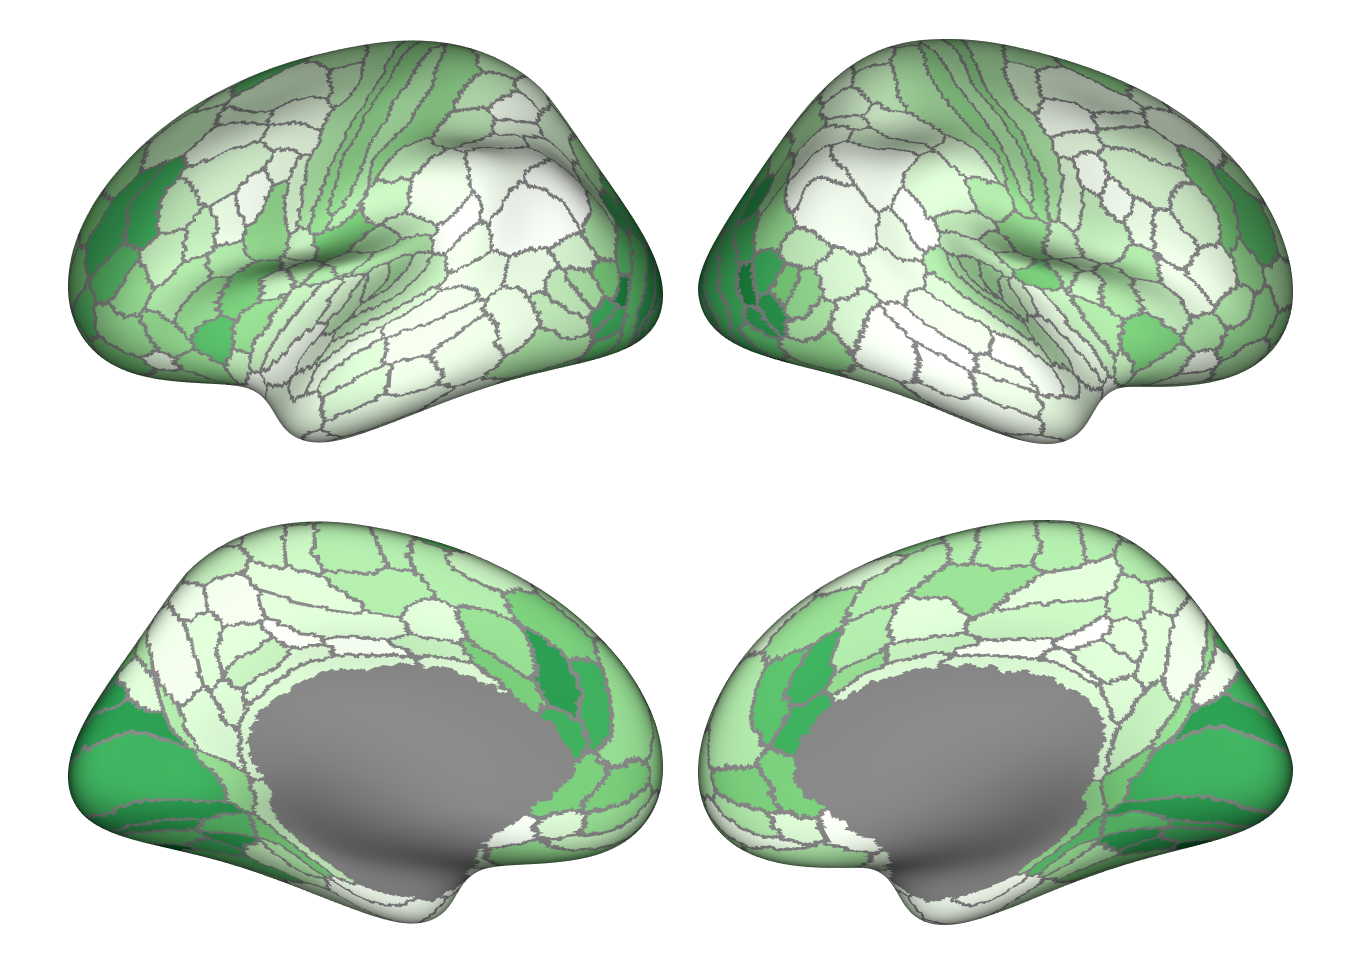

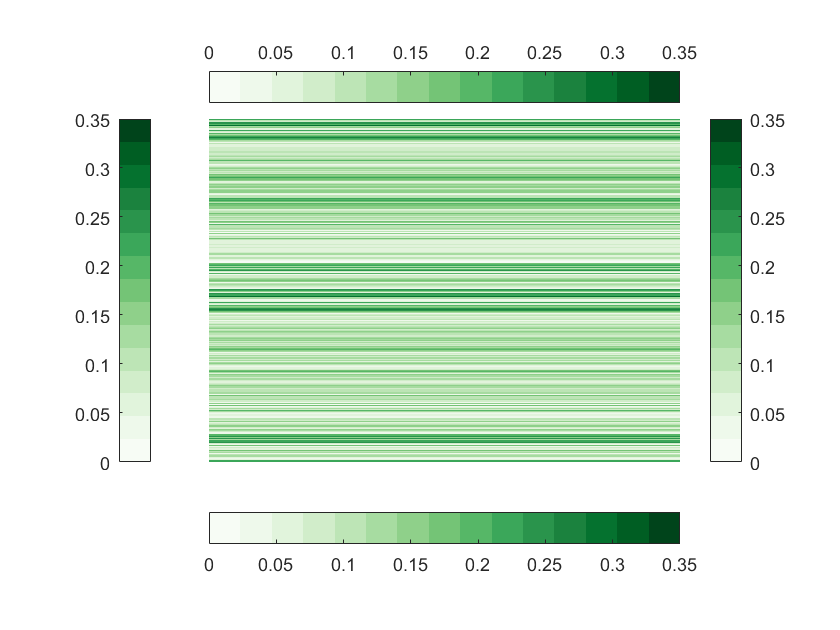

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec, 'cMap',brewermap(15,'Greens'),...
    'viewcMap',1, 'valRange', ([0 0.35]))     